clear

%%%%%%%%%%%% Constants %%%%%%%%%%%%%%%%%%%%%

% Environment
g = 9.81

g = 9.8100

r_E = 6378137 % Earth radius

r_E = 6378137

P_0 = 101325 % Base pressure Pa

P_0 = 101325

L_b = 0.0098 % Temp change K/m

L_b = 0.0098

T_b = 293.15 % Base temp K

T_b = 293.1500

Baro_exp = (-g*0.02897)/(8.3145*L_b)

Baro_exp = -3.4878


h_0 = 0 % Launch pad height

h_0 = 0


% Rocket parameters
A_rocket = pi*0.15^2

A_rocket = 0.0707

S_e = pi*0.02^2

S_e = 0.0013

I_s = 250 % Specific impulse

I_s = 250

T_max = 1000

T_max = 1000

T_min = 500

T_min = 500

Ang_max = deg2rad(10) % Max thrust vector angle

Ang_max = 0.1745

Vec_max = T_max*sin(Ang_max) % Max thrust vector force

Vec_max = 173.6482

Tilt_max = deg2rad(35) % Max safe rocket tilt

Tilt_max = 0.6109

v_land = -1 % landing speed

v_land = -1

tilt_rate_max = 1; % rad/s

t_P2 = 1 % Primary thruster 2% settling time

t_P2 = 1

sigma = 4/t_P2

sigma = 4

t_P = 1/sigma % Primary thruster time constant

t_P = 0.2500

t_S = 0.1 % Secondary thruster time constant

t_S = 0.1000

t_V = 0.1 % Vectoring actuation time constant

t_V = 0.1000


r_S = 0.15 % Moment arm to secondary thrusters

r_S = 0.1500

T_max_s = 1

T_max_s = 1


ang_safe = deg2rad(20)

ang_safe = 0.3491


Ts = 1/100 % sample time

Ts = 0.0100


pos_error = 2 % position error

pos_error = 2

vel_error = 0.05 % velocity error

vel_error = 0.0500

ang_error = deg2rad(2) % angle error

ang_error = 0.0349

rate_error = deg2rad(0.25) % angular rate error

rate_error = 0.0044


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% Initial conditions %%%%%%%%%%%%
Upsilon = 0;
E = 0;
N = 0;

U = 0;
V = 0;
W = 0;

P = 0;
Q = 0;
R = 0;

Phi = deg2rad(0);
Theta = deg2rad(0);
Psi = deg2rad(0);

wind = [0,5,5] % wind speed UNE

wind =      0     5     5


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

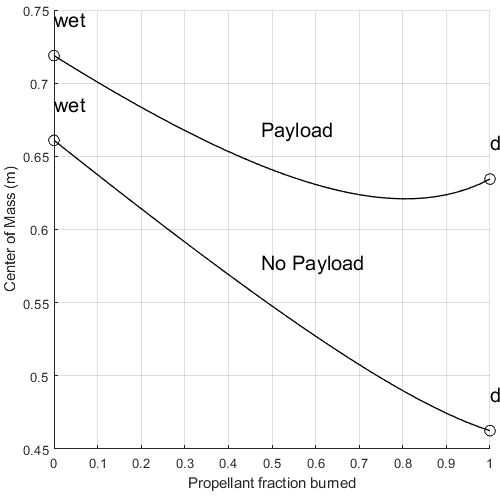

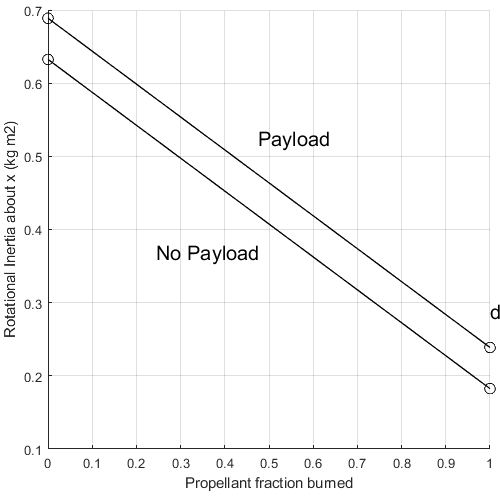

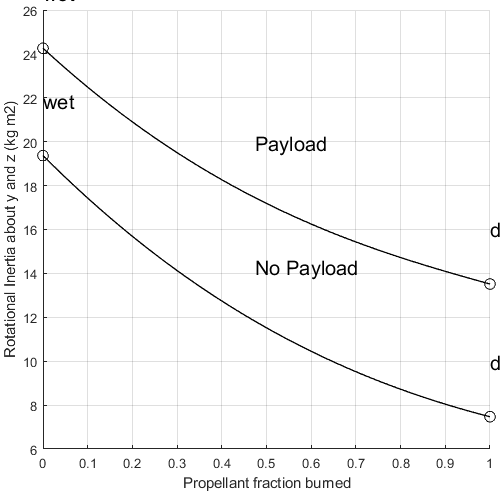

% Rocket paramaters
parameter_vary

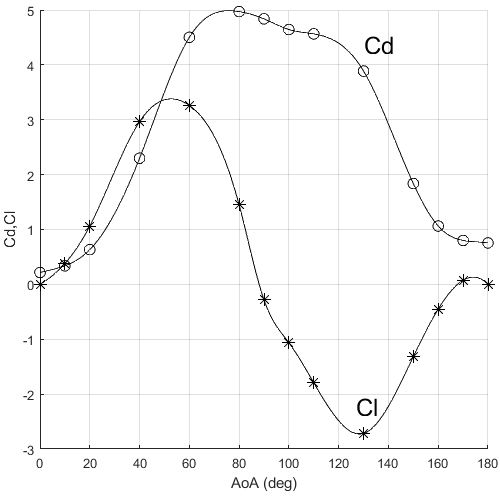

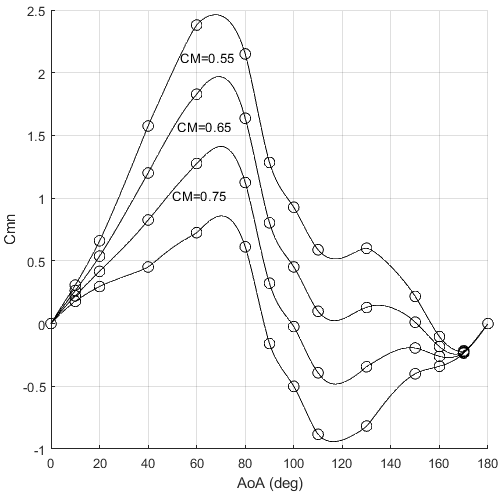

Ct_rot = -1.1887

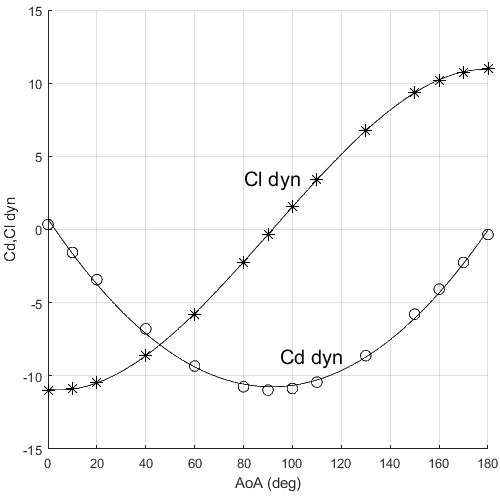

drag_wave_lookup2 = 0.7148

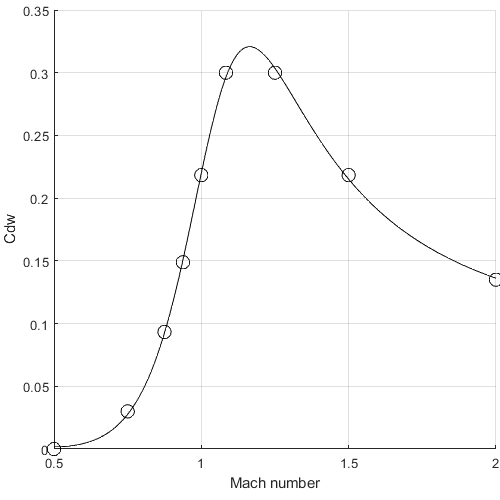

coeff_calc

Mp = 0.0500

zeta = 0.6901

wn = 6.6656

p_s_want =   -4.6000 + 4.8240i
  -4.6000 - 4.8240i


Kp = 20

P_cl =   -5.0000 + 4.7361i
  -5.0000 - 4.7361i


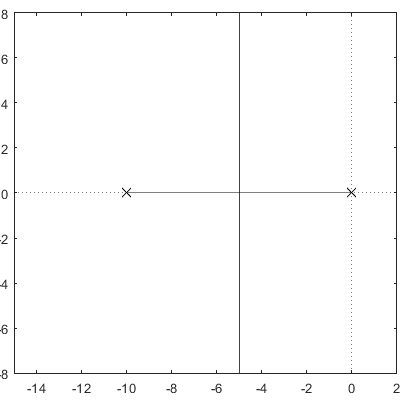

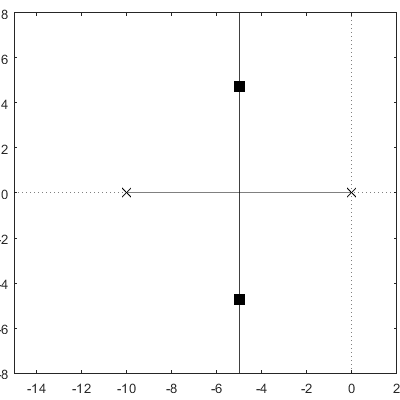

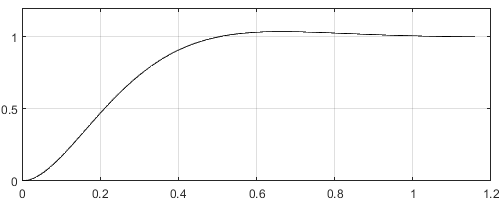

% Controllers
roll_control

Mp = 0.2000

zeta = 0.4559

p_s_want =   -0.8207 + 1.6020i
  -0.8207 - 1.6020i


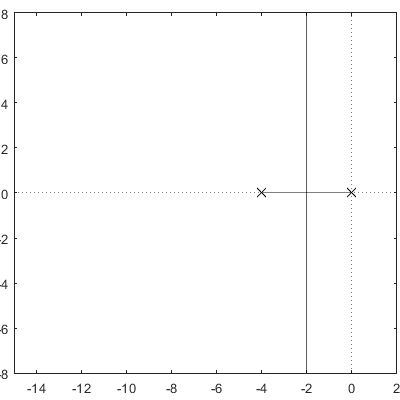

Ki = 21.7910

Kp = 78.4476

P_cl =   -1.8425 + 2.2913i
  -1.8425 - 2.2913i
  -0.3151 + 0.0000i


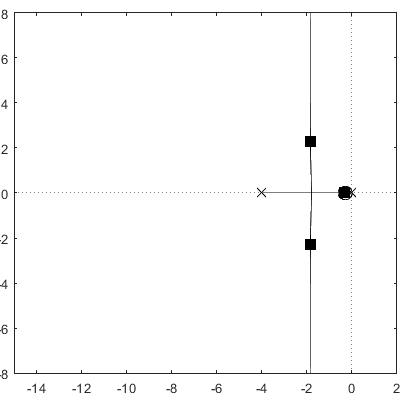

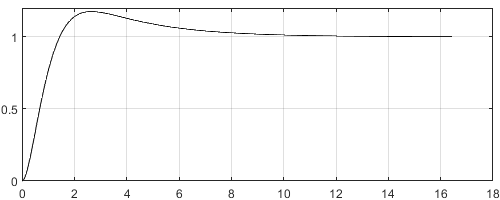

zeta = 1

p_s_want =     -2
    -2


p_z_want =     0.9802
    0.9802


Kp = 0.4500

C_alt =
 
  Kp = 0.45
 
P-only controller.



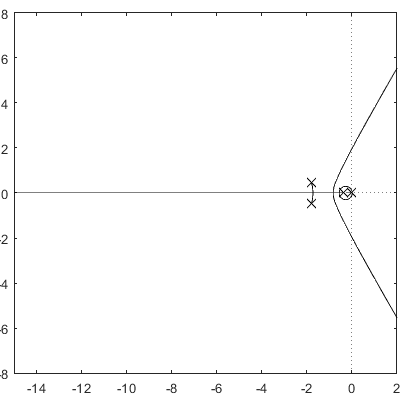

P_cl =   -2.9545 + 0.0000i
  -0.3940 + 1.2066i
  -0.3940 - 1.2066i
  -0.2575 + 0.0000i


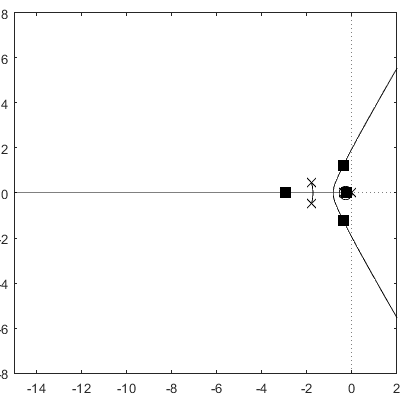

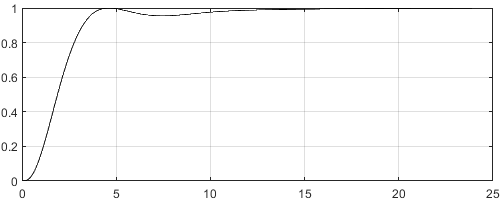

heave_control

Ki = 14.8000

Kp = 162.8000

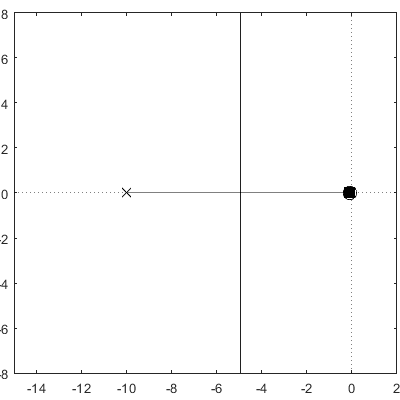

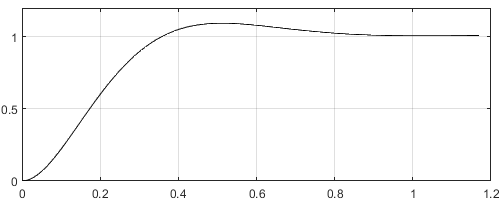

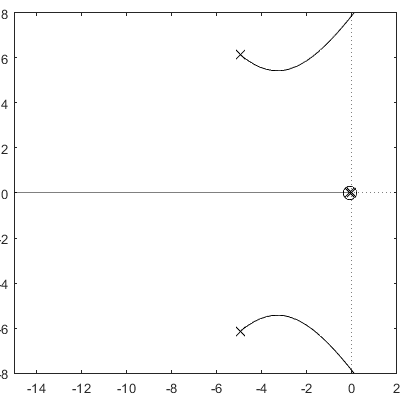

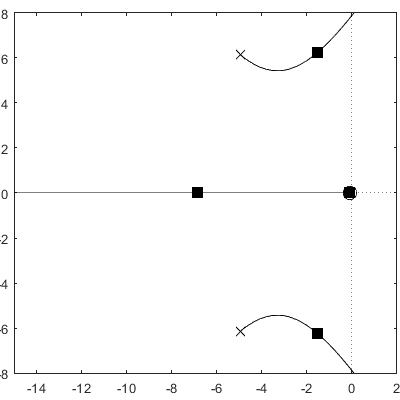

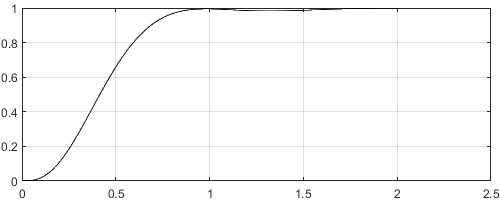

Ki = 1.5000

Kp = 97.5000

C_vel =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 97.5, Ki = 1.5
 
Continuous-time PI controller in parallel form.



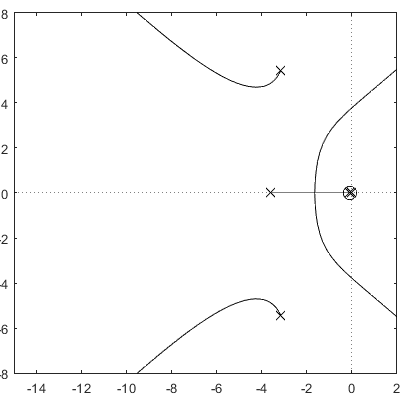

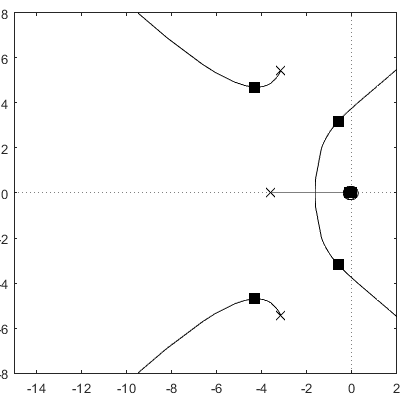

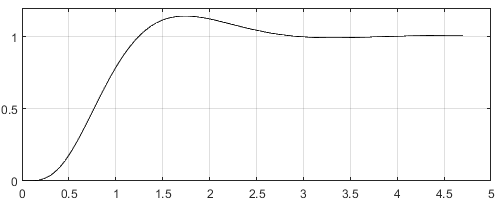

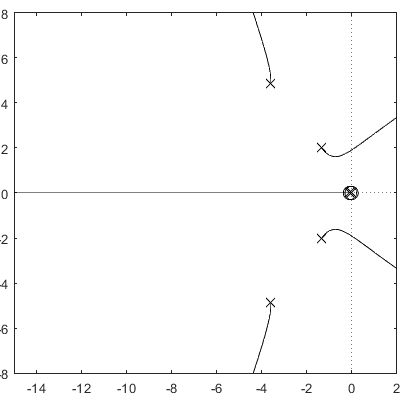

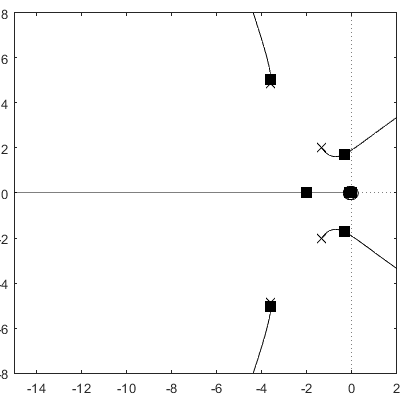

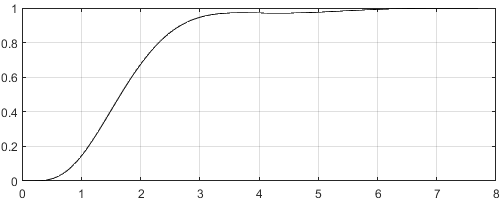

horizontal_control

alt = 30;
% Alt_sequence = [100, 100, 0];
% Pos_sequence = [0, 10, 0;
%                 0, 10, 0];

pos = 30

pos = 30

Alt_sequence = [alt, alt, alt, alt, alt, alt, alt, 0];
Pos_sequence = [0, pos, -pos, -pos, pos, pos, 0, 0;
                0, pos, pos, -pos, -pos, pos, 0, 0];
hold = [0,0,0,0,0,0,0];

% Alt_sequence = [alt, 0];
% Pos_sequence = [0, 0;
%                 0, 0];
% hold = [40,0];